fs = 1./0.001;
tspan = 1:0.001:100;
y_s = 2.*sin(2.*tspan) + sin(0.5 .* tspan);

y_1 = 2.*sin(2.*tspan);
y_1 = y_1';

y_2 = sin(0.5 .* tspan);
y_2 = y_2';

y_s = y_s';
tspan = tspan';

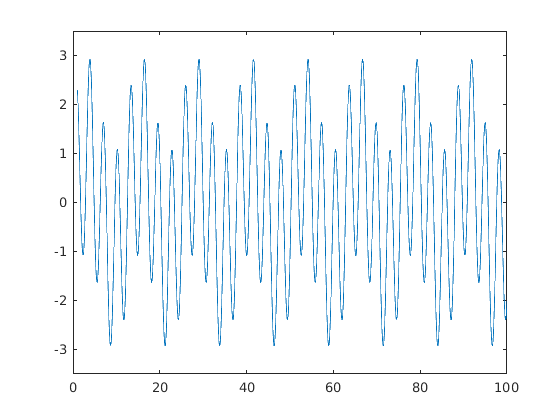

plot(tspan, y_s)
ylim([-3.5, 3.5])

imf_ = emd(y_s, 'Interpolation', 'pchip');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        1     |      0.16963   |  SiftMaxRelativeTolerance
      2      |        1     |    0.0040745   |  SiftMaxRelativeTolerance
      3      |        3     |      0.15119   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16802   |  SiftMaxRelativeTolerance
      5      |        2     |      0.16736   |  SiftMaxRelativeTolerance
      6      |        3     |     0.068927   |  SiftMaxRelativeTolerance
      7      |        2     |     0.079171   |  SiftMaxRelativeTolerance
The decomposition stopped because the number of extrema of the residual signal is less than 'MaxNumExtrema'.


[hs,f,t,imfinsf,imfinse] = hht(imf_,fs);

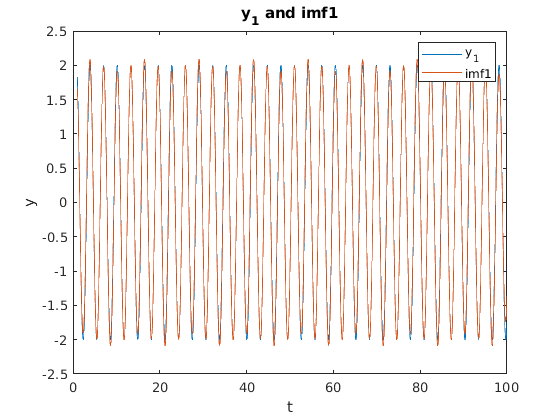

%%% Analyzing imf1 compared to y_1
clf
plot(tspan, y_1)
hold on
plot(tspan, imf_(:,1))
title("y_1 and imf1")
ylabel("y")
xlabel("t")
legend('y_1', 'imf1')

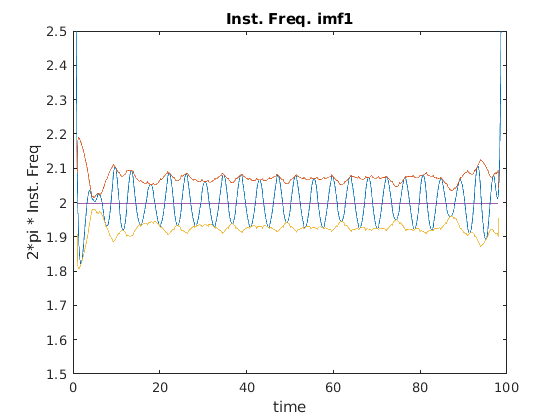

%%% Instantaneous frequency of the first mode
clf
plot(t, 2.*pi.*imfinsf(:,1))
hold on
% Grab average of the inst freq.
[yupper1,ylower1] = envelope( 2.*pi.*imfinsf(1000:98001,1) );
plot(t(1000:98001,1), yupper1)
plot(t(1000:98001,1), ylower1)
plot(t(1000:98001,1), (ylower1+yupper1)./2)
ylim([1.5, 2.5])
title("Inst. Freq. imf1")
ylabel("2*pi * Inst. Freq")
xlabel("time")

%%% We can see that the average of the instantaneous frequency
%%% of imf1 matches the frequency of y_1

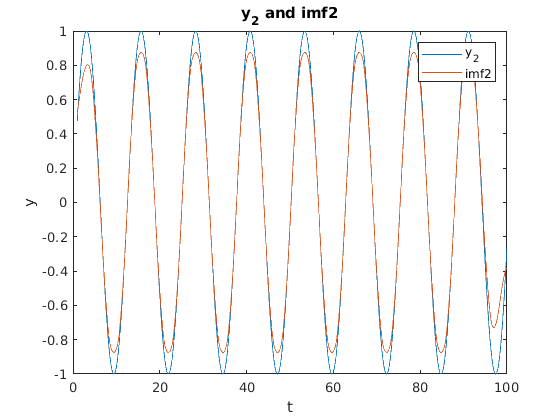

%%% Analyzing imf2 compared to y_1
clf
plot(tspan, y_2)
hold on
plot(tspan, imf_(:,2))
title("y_2 and imf2")
ylabel("y")
xlabel("t")
legend('y_2', 'imf2')

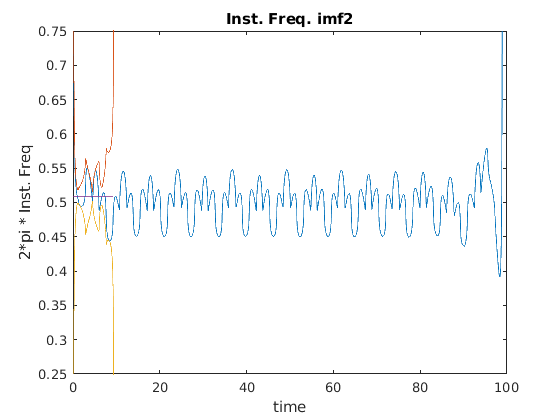

% Instantaneous frequency of the 2nd mode
clf
plot(t, 2.*pi.*imfinsf(:,2))
hold on
[yupper2,ylower2] = envelope( 2.*pi.*imfinsf(150:9351,2) );
plot(t(150:9351,1), yupper2)
plot(t(150:9351,1), ylower2)
plot(t(150:9351,1), (ylower2+yupper2)./2)
ylim([0.25, 0.75])
title("Inst. Freq. imf2")
ylabel("2*pi * Inst. Freq")
xlabel("time")

%%% We can see that the average of the instantaneous frequency
%%% of imf2 matches the frequency of y_2

So it seems that the HHT can uncover the two sin waves and their respective

frequencies

## Can HHT uncover an increaing frequency?

fs =1000;
clf

tspan = 1:0.001:150;
%y_s = 2.*sin(2.*tspan) + sin(0.01.*tspan .* tspan);

y_1 = 2.*sin(2.*tspan);
y_1 = y_1';

y_2 = sin(0.05.*sqrt(tspan) .* tspan);
y_2 = y_2';

y_s = y_2;
tspan = tspan';

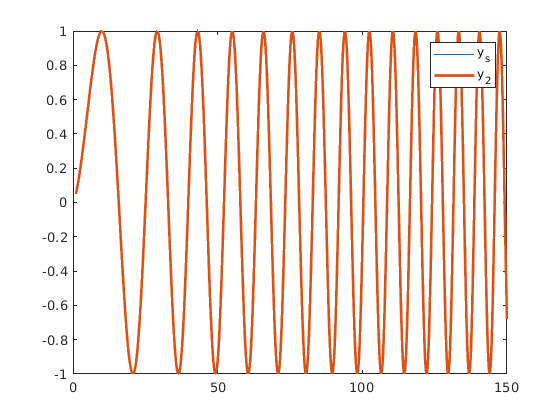

plot(tspan, y_s)
hold on
plot(tspan, y_2, 'LineWidth', 2.0)
legend("y_s", "y_2")

imf_ = emd(y_s, 'Interpolation', 'pchip');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        1     |     0.024707   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1406   |  SiftMaxRelativeTolerance
      3      |        3     |     0.090391   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11354   |  SiftMaxRelativeTolerance
      5      |        3     |     0.026075   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15538   |  SiftMaxRelativeTolerance
The decomposition stopped because the number of extrema of the residual signal is less than 'MaxNumExtrema'.


% Perform ensemble EMD
Ne = 300;
sigma_e = 0.5; % still works with sigma = 1.5
rng(50);
[m,n] = size(y_s);

avg_trials = [];
for trial_ =1:1:Ne
    noise_ = randn(m,1).*sigma_e;
    imf_ = emd(y_s + noise_, 'Interpolation', 'pchip');
    
    
    % add on to running avg
    if trial_ == 1
        avg_trials = imf_(:,1:9);
    end
    if trial_ >1
        current_N  = trial_-1;
        avg_trials = avg_trials + imf_(:,1:9);        
    end
end

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030695   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060198   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072226   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071067   |  SiftMaxRelativeTolerance
      5      |        2     |     0.072306   |  SiftMaxRelativeTolerance
      6      |        2     |      0.10479   |  SiftMaxRelativeTolerance
      7      |        3     |     0.056761   |  SiftMaxRelativeTolerance
      8      |        3     |      0.10997   |  SiftMaxRelativeTolerance
      9      |        3     |      0.10354   |  SiftMaxRelativeTolerance
     10      |        1     |      0.16468   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.
Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031262   |  SiftMaxRelativeTolerance


imf_eemd = avg_trials./Ne;

imf_= emd(y_s, 'Interpolation', 'spline');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        1     |     0.023344   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12579   |  SiftMaxRelativeTolerance
      3      |        3     |     0.022926   |  SiftMaxRelativeTolerance
      4      |        3     |     0.051951   |  SiftMaxRelativeTolerance
      5      |        4     |     0.078225   |  SiftMaxRelativeTolerance
The decomposition stopped because the number of extrema of the residual signal is less than 'MaxNumExtrema'.


[hs,f,t,imfinsf,imfinse] = hht(imf_eemd, fs./2);

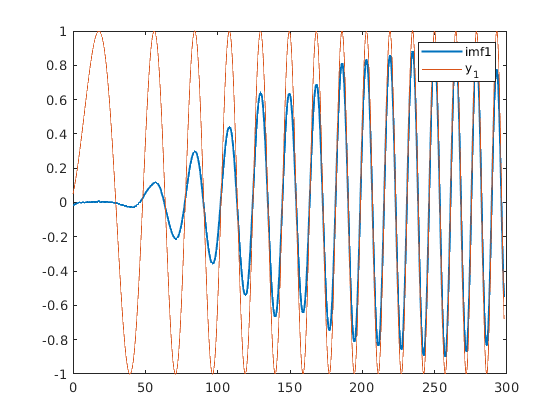

clf
plot(t,imf_eemd(:,9), 'LineWidth', 1.5)
hold on
plot(t, y_2)
legend("imf1", "y_1")


hold off

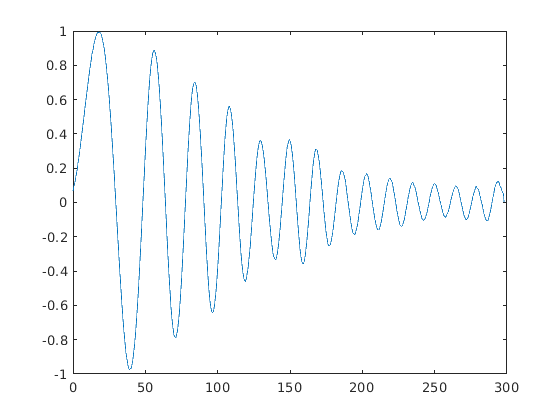

clf
plot(t, y_2-imf_eemd(:,8)-imf_eemd(:,9))

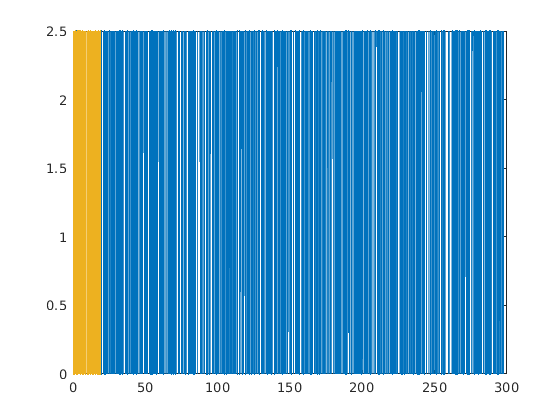

%%% Check inst freq. of imf 1
clf
plot(t, 2.*pi.*imfinsf(:,5))
hold on
% Grab average of the inst freq.
[yupper1,ylower1] = envelope( 2.*pi.*imfinsf(100:9801,5) );
plot(t(100:9801,1), yupper1)
plot(t(100:9801,1), ylower1)
plot(t(100:9801,1), (ylower1+yupper1)./2)
ylim([0, 2.5])

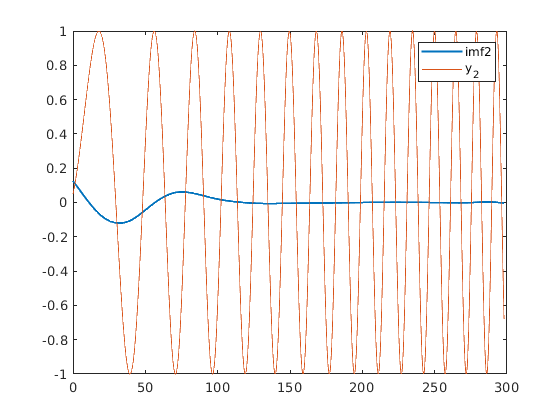

clf
plot(t,imf_(:,2), 'LineWidth', 1.5)
hold on
plot(t, y_2)
legend("imf2", "y_2")


hold off

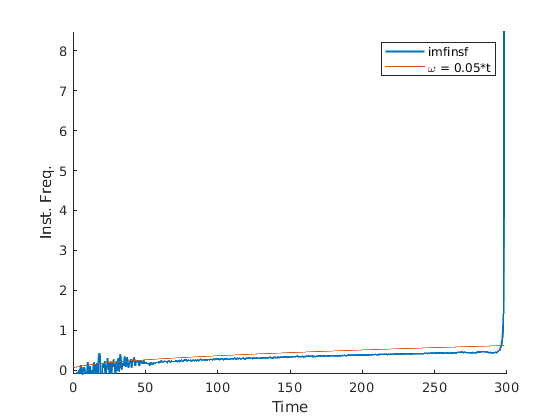

%%% Check inst freq. of imf 2
clf
%plot(t, 2.*pi.*imfinsf(:,8))
hold on

plot(t, 2.*pi.*imfinsf(:,9),'LineWidth', 1.5)

% Grab average of the inst freq.
[yupper2,ylower2] = envelope( 2.*pi.*imfinsf(1000:9700,2) );
%plot(t(1000:9700,1), yupper2)
%plot(t(1000:9700,1), ylower2)
%plot(t(1000:9700,1), (ylower2+yupper2)./2)
plot(t, 0.05.*sqrt(tspan) )
ylim([-0.1, 8.5])
legend("imfinsf","\omega = 0.05*t")
ylabel("Inst. Freq.")
xlabel("Time")

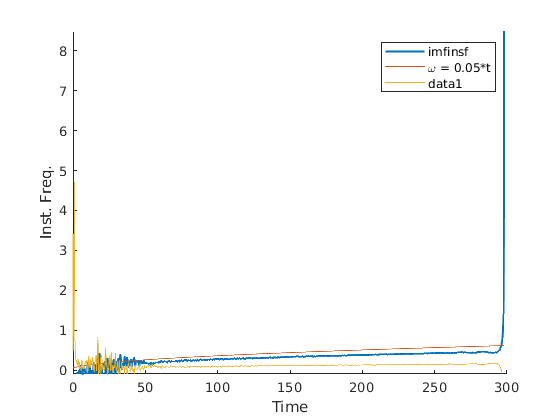

plot(t, 0.05.*sqrt(tspan)-2.*pi.*imfinsf(:,9))

clf
clear

fs =1000;

tspan = 1:0.001:150;
%y_s = 2.*sin(2.*tspan) + sin(0.01.*tspan .* tspan);

y_1 = 2.*sin(2.*tspan);
y_1 = y_1';

y_2 = 0.05.*tspan.*sin(0.5.* tspan);
y_2 = y_2';

y_s = y_2;
tspan = tspan';

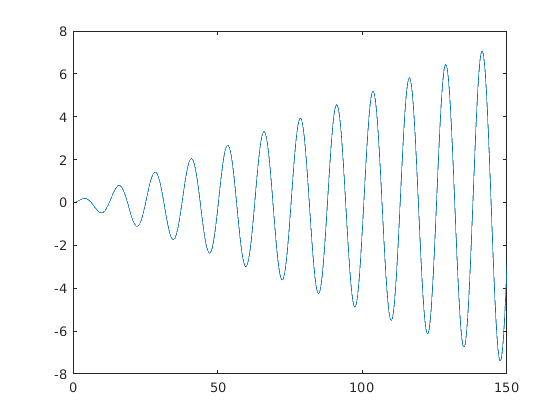

plot(tspan, y_2)

% Perform ensemble EMD
Ne = 300;
sigma_e = 0.5; % still works with sigma = 1.5
rng(50);
[m,n] = size(y_s);

avg_trials = [];
for trial_ =1:1:Ne
    noise_ = randn(m,1).*sigma_e;
    imf_ = emd(y_s + noise_, 'Interpolation', 'pchip');
    
    
    % add on to running avg
    if trial_ == 1
        avg_trials = imf_(:,1:9);
    end
    if trial_ >1
        current_N  = trial_-1;
        avg_trials = avg_trials + imf_(:,1:9);        
    end
end

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030663   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059972   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071481   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075181   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11988   |  SiftMaxRelativeTolerance
      6      |        3     |     0.058301   |  SiftMaxRelativeTolerance
      7      |        3     |      0.12413   |  SiftMaxRelativeTolerance
      8      |        3     |     0.063216   |  SiftMaxRelativeTolerance
      9      |        1     |      0.10643   |  SiftMaxRelativeTolerance
     10      |        2     |     0.061056   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.
Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031153   |  SiftMaxRelativeTolerance


imf_eemd = avg_trials./Ne;

imf_= emd(y_s, 'Interpolation', 'spline');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        1     |   7.0079e-05   |  SiftMaxRelativeTolerance
The decomposition stopped because the current energy ratio is greater than 'MaxEnergyRatio'.


[hs,f,t,imfinsf,imfinse] = hht(imf_, fs./2);

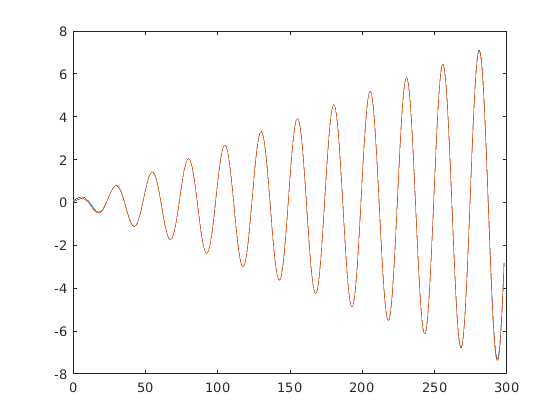

clf
plot(t, imf_(:,1))
hold on
plot(t, y_2)

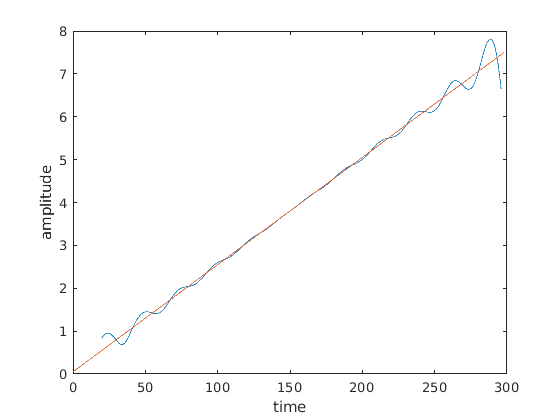

clf
plot(t(10000:148000), sqrt(imfinse(10000:148000,1)))
hold on
plot(t, 0.05.*tspan)
ylabel("amplitude")
xlabel("time")

clf
clear

fs =1000;

tspan = 1:0.001:150;
%y_s = 2.*sin(2.*tspan) + sin(0.01.*tspan .* tspan);

y_1 = 2.*sin(2.*tspan);
y_1 = y_1';

y_2 = exp(-0.01.*tspan).*sin(0.5.* tspan);
y_2 = y_2';

y_s = y_2;
tspan = tspan';

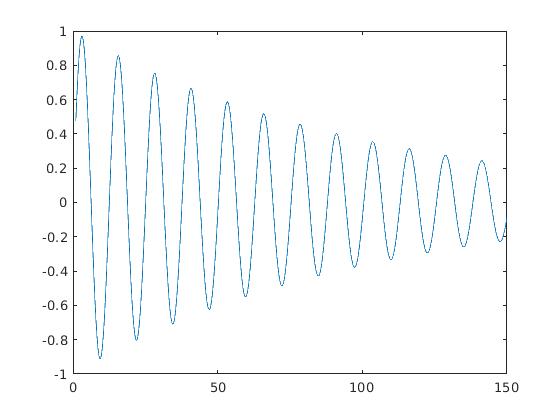

plot(tspan, y_2)

% Perform ensemble EMD
Ne = 30;
sigma_e = 0.5; % still works with sigma = 1.5
rng(50);
[m,n] = size(y_s);

avg_trials = [];
for trial_ =1:1:Ne
    noise_ = randn(m,1).*sigma_e;
    imf_ = emd(y_s + noise_, 'Interpolation', 'pchip');
    
    
    % add on to running avg
    if trial_ == 1
        avg_trials = imf_(:,1:9);
    end
    if trial_ >1
        current_N  = trial_-1;
        avg_trials = avg_trials + imf_(:,1:9);        
    end
end

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030668   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060153   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071311   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072171   |  SiftMaxRelativeTolerance
      5      |        2     |     0.070048   |  SiftMaxRelativeTolerance
      6      |        2     |     0.087733   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11483   |  SiftMaxRelativeTolerance
      8      |        3     |     0.051842   |  SiftMaxRelativeTolerance
      9      |        6     |     0.028714   |  SiftMaxRelativeTolerance
     10      |        1     |       0.1183   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.
Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031279   |  SiftMaxRelativeTolerance


imf_eemd = avg_trials./Ne;

imf_= emd(y_s, 'Interpolation', 'spline');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        1     |   0.00010111   |  SiftMaxRelativeTolerance
      2      |        2     |     0.084153   |  SiftMaxRelativeTolerance
The decomposition stopped because the current energy ratio is greater than 'MaxEnergyRatio'.


[hs,f,t,imfinsf,imfinse] = hht(imf_, fs./2);

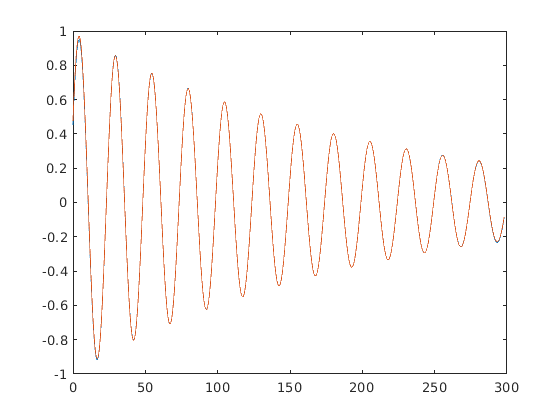

clf
plot(t, imf_(:,1))
hold on
plot(t, y_2)

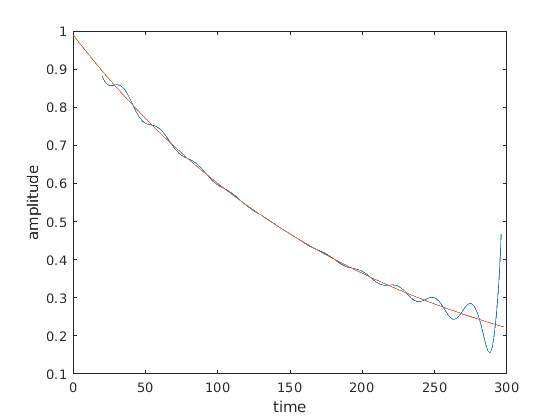

clf
plot(t(10000:148000), sqrt(imfinse(10000:148000,1)))
hold on
plot(t, exp(-0.01.*tspan))
ylabel("amplitude")
xlabel("time")

%% Detecting two components w/ time-varying amplitudes and frequencies

clf
clear

fs =1000;

tspan = 1:0.001:150;
%y_s = 2.*sin(2.*tspan) + sin(0.01.*tspan .* tspan);

y_1 = exp(-0.01.*tspan).*sin(0.01.*tspan.*tspan);
y_1 = y_1';

y_2 = exp(-0.02.*tspan).*sin((1./150).*tspan.* tspan);
y_2 = y_2';



y_s = y_1 + y_2;
tspan = tspan';

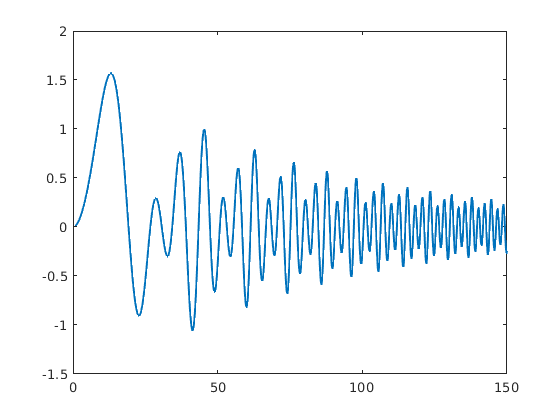

clf
plot(tspan, y_s,'LineWidth', 1.5)
hold on

%plot(tspan, y_1)
%plot(tspan, y_2)

% Perform ensemble EMD
Ne = 750;
sigma_e = 1.75; % still works with sigma = 1.5
rng(50);
[m,n] = size(y_s);

avg_trials = [];
for trial_ =1:1:Ne
    noise_ = randn(m,1).*sigma_e;
    imf_ = emd(y_s + noise_, 'Interpolation', 'pchip', 'MaxNumIMF', 12);
    
    
    % add on to running avg
    if trial_ == 1
        avg_trials = imf_(:,1:12);
    end
    if trial_ >1
        current_N  = trial_-1;
        avg_trials = avg_trials + imf_(:,1:12);        
    end
end

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030692   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060179   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071374   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071032   |  SiftMaxRelativeTolerance
      5      |        2     |     0.069382   |  SiftMaxRelativeTolerance
      6      |        2     |      0.09095   |  SiftMaxRelativeTolerance
      7      |        2     |     0.084905   |  SiftMaxRelativeTolerance
      8      |        3     |      0.10385   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10997   |  SiftMaxRelativeTolerance
     10      |        2     |      0.09657   |  SiftMaxRelativeTolerance
     11      |        2     |      0.06246   |  SiftMaxRelativeTolerance
     12      |        3     |     0.023155   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reach

imf_eemd = avg_trials./Ne;

imf_= imf_eemd;%emd(y_s, 'Interpolation', 'spline');
[hs,f,t,imfinsf,imfinse] = hht(imf_eemd, fs./2);

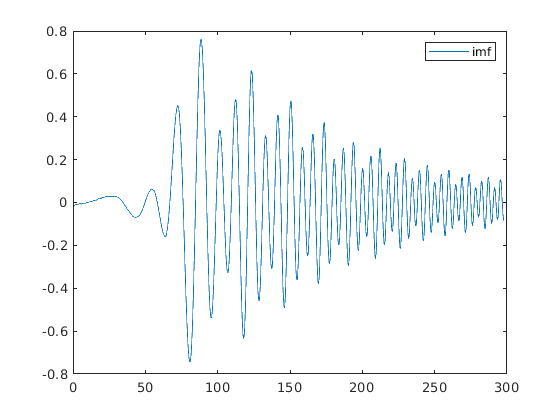

clf
plot(t, imf_(:,9))
hold on
%plot(t, y_1)
legend("imf","y_i")

%plot(t, y_1-imf_eemd(:,9),'LineWidth',1.5,'Color','blue')

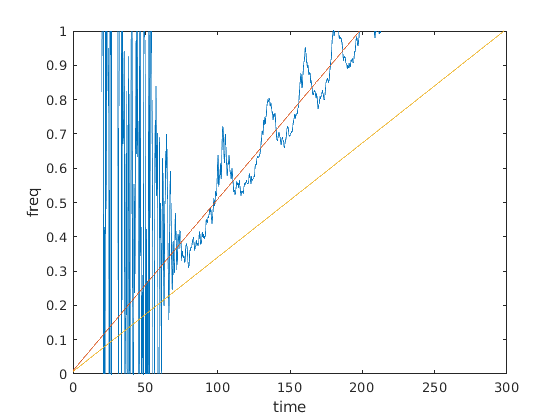

clf
plot(t(10000:148000), 2.*pi.*imfinsf(10000:148000,9))
hold on
plot(t, (1./100).*tspan)
plot(t, (1./150).*tspan)
ylabel("freq")
xlabel("time")
ylim([0,1])

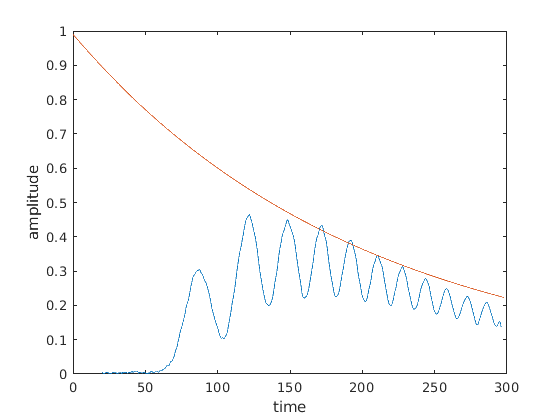

clf
plot(t(10000:148000), sqrt(imfinse(10000:148000,9)))
hold on
plot(t, exp(-(1./100).*tspan))
ylabel("amplitude")
xlabel("time")

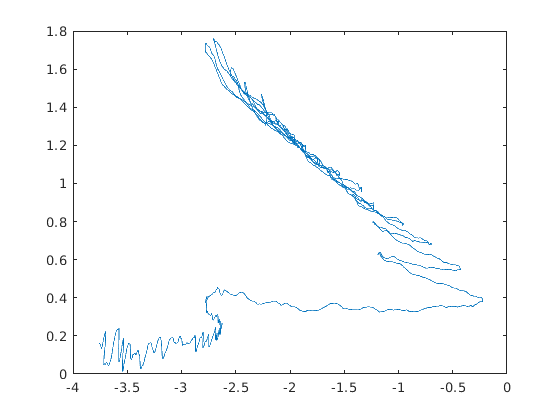

clf
plot(log(sqrt(imfinse(10000:148000,9))), 2.*pi.*imfinsf(10000:148000,9))

## Can we detect a phase?

clf
clear

fs =1000;

tspan = 1:0.001:150;
%y_s = 2.*sin(2.*tspan) + sin(0.01.*tspan .* tspan);

y_1 = exp(-0.01.*tspan).*sin((0.01.*tspan) .*tspan);
y_1 = y_1';

y_2 = exp(-0.02.*tspan).*sin((1./150).*tspan.* tspan);
y_2 = y_2';

[m,n] = size(tspan);
y_3 = sin(5).*ones(m,n);

y_s = y_1;
tspan = tspan';

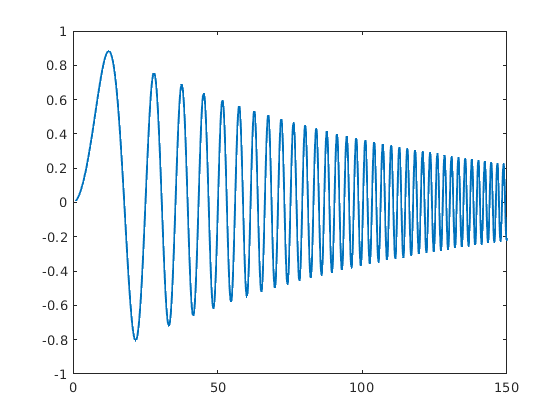

clf
plot(tspan, y_s,'LineWidth', 1.5)
hold on

%plot(tspan, y_1)
%plot(tspan, y_2)

% Perform ensemble EMD
Ne = 500;
sigma_e = 0.5; % still works with sigma = 1.5
rng(50);
[m,n] = size(y_s);

avg_trials = [];
for trial_ =1:1:Ne
    noise_ = randn(m,1).*sigma_e;
    imf_ = emd(y_s + noise_, 'Interpolation', 'pchip');
    
    
    % add on to running avg
    if trial_ == 1
        avg_trials = imf_(:,1:10);
    end
    if trial_ >1
        current_N  = trial_-1;
        avg_trials = avg_trials + imf_(:,1:10);        
    end
end
imf_eemd = avg_trials./Ne;

imf_= emd(y_s, 'Interpolation', 'spline');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        1     |     0.030528   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13346   |  SiftMaxRelativeTolerance
      3      |        2     |     0.042518   |  SiftMaxRelativeTolerance
      4      |        3     |      0.15747   |  SiftMaxRelativeTolerance
      5      |        2     |     0.063904   |  SiftMaxRelativeTolerance
The decomposition stopped because the number of extrema of the residual signal is less than 'MaxNumExtrema'.


[hs,f,t,imfinsf,imfinse] = hht(imf_, fs./2);

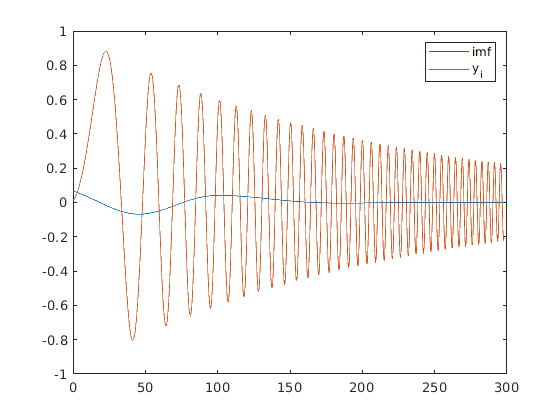

clf
plot(t, imf_(:,3))
hold on
plot(t, y_1)
legend("imf","y_i")

%plot(t, y_1-imf_eemd(:,9),'LineWidth',1.5,'Color','blue')

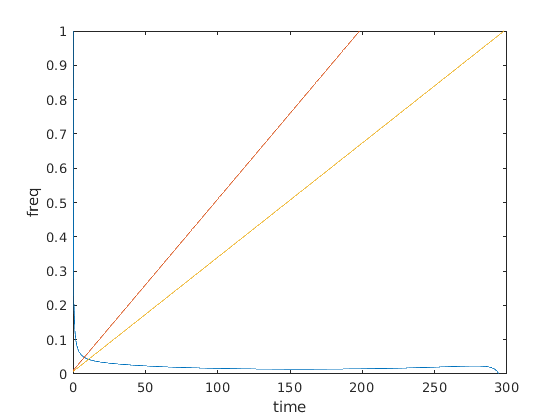

clf
plot(t(1:148000), 2.*pi.*imfinsf(1:148000,5))
hold on
plot(t, (1./100).*tspan)
plot(t, (1./150).*tspan)
ylabel("freq")
xlabel("time")
ylim([0,1])

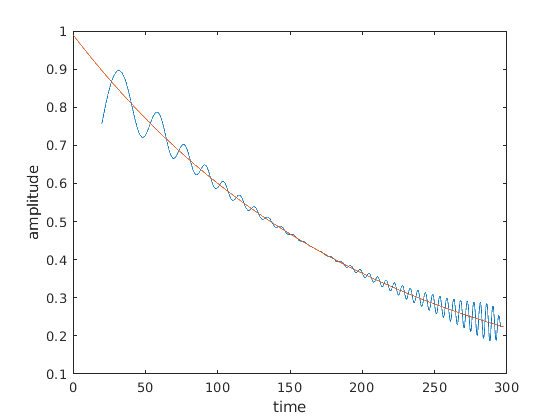

clf
plot(t(10000:148000), sqrt(imfinse(10000:148000,1)))
hold on
plot(t, exp(-(1./100).*tspan))
ylabel("amplitude")
xlabel("time")